denoise the signal

% Read data
f_noisy = readmatrix('noisy_signal.csv');

% Parameters
n = 1000;
w1 = 10^(-4);
w2 = 5 * 10^(-4);
w3 = 10^(-3);

% Identity matrix and Laplacian matrix
I = diag(ones(n, 1), 0);
L = diag(ones(n, 1), 0) - diag(ones(n-1, 1), 1);
L = 999 * L(1:end-1, :);  % Remove last row

% Solve linear systems with different regularization weights
x1 = (I + w1 * (L') * L) \ f_noisy;
x2 = (I + w2 * (L') * L) \ f_noisy;
x3 = (I + w3 * (L') * L) \ f_noisy;

plot the denoised signal

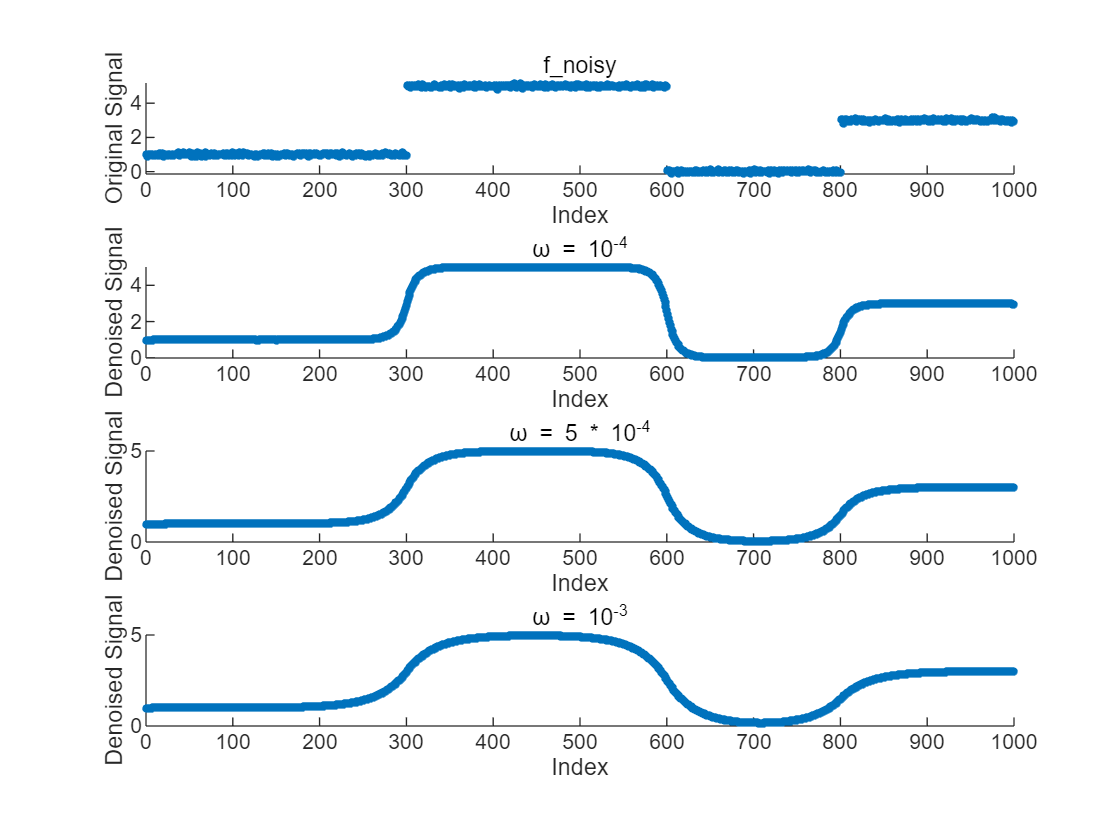

% Plot the results
figure;

% Plot f_noisy
subplot(4, 1, 1);
scatter(1:length(f_noisy), f_noisy, 10, 'filled');
title('f\_noisy');
xlabel('Index');
ylabel('Original Signal');

% Plot x1
subplot(4, 1, 2);
scatter(1:length(x1), x1, 10, 'filled');
title('ω = 10^{-4}');
xlabel('Index');
ylabel('Denoised Signal');

% Plot x2
subplot(4, 1, 3);
scatter(1:length(x2), x2, 10, 'filled');
title('ω = 5 * 10^{-4}');
xlabel('Index');
ylabel('Denoised Signal');

% Plot x3
subplot(4, 1, 4);
scatter(1:length(x3), x3, 10, 'filled');
title('ω = 10^{-3}');
xlabel('Index');
ylabel('Denoised Signal');